Let's investigate whether there is any relation between the position and speeds of the wheel

data = readtable('data/matlab_table/data_active_pos_fb_response_only.xml');
summed_speeds = cumsum(data.wheel_speed,2,'omitmissing'); %sum over rows and ignore nans
num_speed_values = sum(~isnan(data.wheel_speed),2);


data.wheel_pos = summed_speeds ./ num_speed_values ; % NOTE ./ operator
data.mean_wheel = mean( data.wheel_speed, 2, 'omitmissing');


make a scatter plot for datapoints in trials where the general motion was either left or right

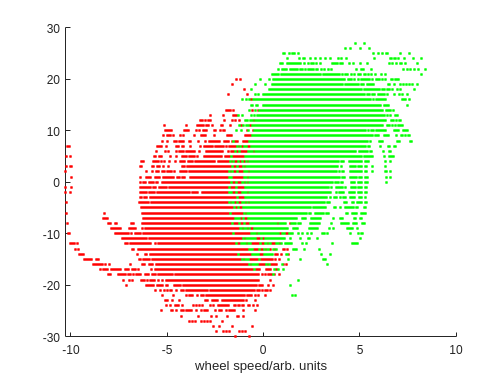

left_data = data(data.mean_wheel<0,:);
right_data = data(data.mean_wheel>0,:);

hold on 
scatter(left_data.wheel_pos, left_data.wheel_speed,  'red', '.')
scatter(right_data.wheel_pos, right_data.wheel_speed, 'green','.')
hold off

xlabel('wheel position/arb. units')
ylabel('wheel speed/arb. units')

WOW it seems that there is some correlation. When the wheel speed is faster to the right, the position is more likely to be to the right - that may be self-evident. 

What is interesting is that for trials when the wheel was turned to the right (green data points), there are very few points with a negative wheel speed.

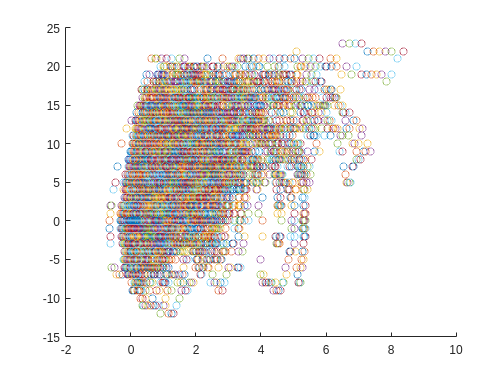

ans =      0     0     0     0     0    -2     0     0     0     0     0     0    -1     1     0     0     0    -1     0     0    -1     0     0     0     1     0     0    -1     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     0     0     0    -1